# Auxiliary function for the application of the Dirichlet and Neumann Boundary conditions

## 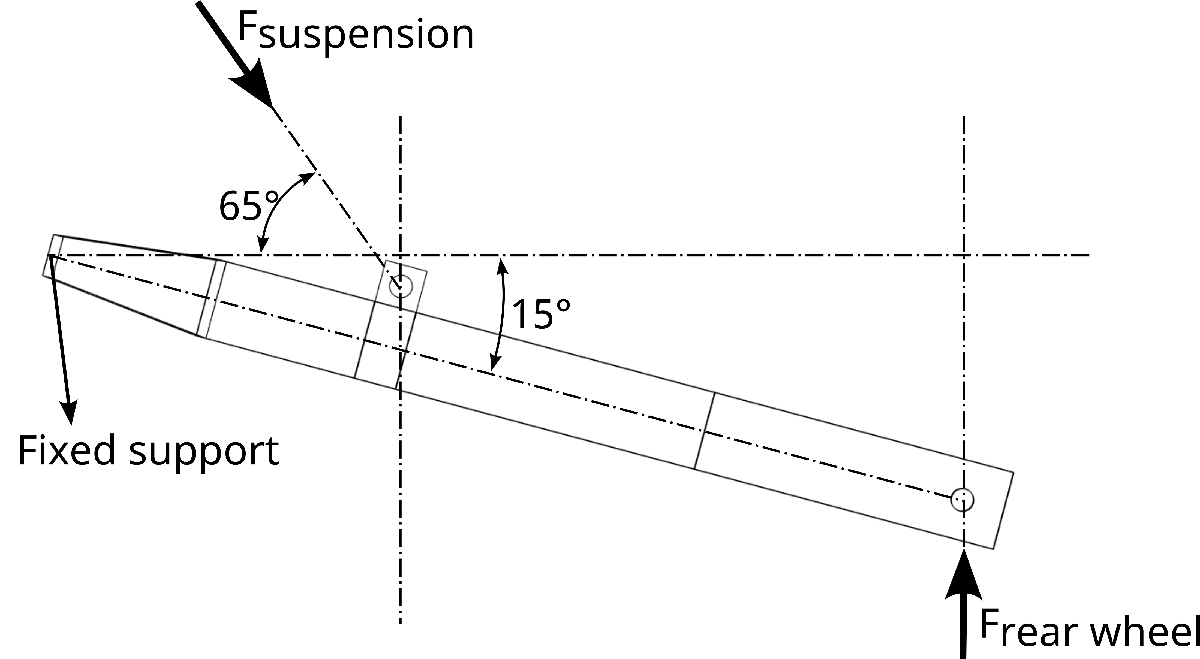

function structModel = applyBoundaryConditions(structModel)

### *Dirichlet Boundary Conditions* (DBC)

PtDBC = [697.034,-119.000,-28.254]*1e-3; % We know that this point is on the surface that is fixed
faceIDDBC = nearestFace(structModel.Geometry, PtDBC);
% structuralBC(structModel, "Face", faceIDDBC, "Constraint", "fixed");
structModel.FaceBC(faceIDDBC) = faceBC(Constraint="fixed");

### *Neumann Boundary Conditions* (NBC)

The total force from the weight of the motorbike and the rider is given by the following formula:


$$M_g = \left( M_{\text{mce}} + M_{\text{rider}} \right) = 2,118.96 N$$


#### Load at the rear part of the swingarm

The rear part of the swingarm is subject to roughly $55\% \cdot M_g = 1,165.428 \; \text{N}$, where $M_g$ is the total weight. The surface area of each of the holes where the rear axle is mounted is $1507,96448 \; \text{mm}^2 \times 1e-6 = 0.0015 \; \text{m}^2$. Thus, the total application area of the $1,165.428 \; \text{N}$ load is $0.0015 \; \text{m}^2$. Therefore, the surface traction at these locations should be $t_{\text{rear}} = \frac{55\% \cdot M_g}{2\cdot A_{rear}} = \frac{1,165.428 \; \text{N}}{0.003 \; \text{m}^2} = 388476 \; \text{Pa}$. The load is applied vertically, see the sketch above

PtsRearNBC = [54.832,-223.000,-208.614
    54.832,-15.000,-208.614]*1e-3; % We know that these points are located on the front suspension mounts
faceIDsRearNBC = nearestFace(structModel.Geometry, PtsRearNBC);
tRear = 388476;
structModel.FaceLoad(faceIDsRearNBC) = faceLoad(SurfaceTraction=[0; 0; tRear]);

#### Load at the front part of the swingarm

Similar for the front part of the swingarm, this is subject to the rest $45\% \cdot M_g = 953.532 \; \text{N}$, where $M_g$ is the total weight. The surface area of each of the holes where the suspension is mounted is $100,530965  \; \text{mm}^2 \times 1e-6 = 1.00530965e-04 \; \text{m}^2$. Therefore, the surface traction at these locations should be $t_{\text{front}} = \frac{45\% \cdot M_g}{2\cdot A_{front}} = \frac{953.532 \; \text{N}}{2.0106193e-04 \; \text{m}^2} = 4.742 \times 1e6 \; \text{Pa}$.

PtsFrontNBC = [450.357,-133.000,-58.117
               450.357,-105.000,-58.117]*1e-3; % We know that these points are located on the rear wheel mounts
faceIDsFrontNBC = nearestFace(structModel.Geometry, PtsFrontNBC);
tFront = 4.742e6;
phiDeg = 65;
phiRad = deg2rad(phiDeg);
structModel.FaceLoad(faceIDsFrontNBC) = faceLoad(SurfaceTraction=[-tFront*cos(phiRad); 0; -tFront*sin(phiRad)]);

end